clc;
clear all;
close all;

## generate data

tic

run('Q310_Basic.mlx')

sys_dis_open =
 
   0.1604 z^2 - 0.1958 z + 0.07861
  ----------------------------------
  z^3 - 1.937 z^2 + 1.122 z - 0.1421
 
Sample time: 0.24388 seconds
Discrete-time transfer function.



c =          0    0.1604   -0.1958    0.0786


d =     1.0000   -1.9367    1.1220   -0.1421


sys_cont_close =
 
     7.8 s^3 + 205.7 s^2 + 601.4 s + 1276
  -------------------------------------------
  s^4 + 15.8 s^3 + 212.7 s^2 + 608.4 s + 1276
 
Continuous-time transfer function.


sys_dis_close =
 
  0.1328 z^3 - 0.3505 z^2 + 0.3048 z - 0.08705
  --------------------------------------------
  z^4 - 3.73 z^3 + 5.24 z^2 - 3.288 z + 0.778
 
Sample time: 0.015887 seconds
Discrete-time transfer function.



c1 =          0    0.1328   -0.3505    0.3048   -0.0871


d1 =     1.0000   -3.7296    5.2395   -3.2878    0.7780


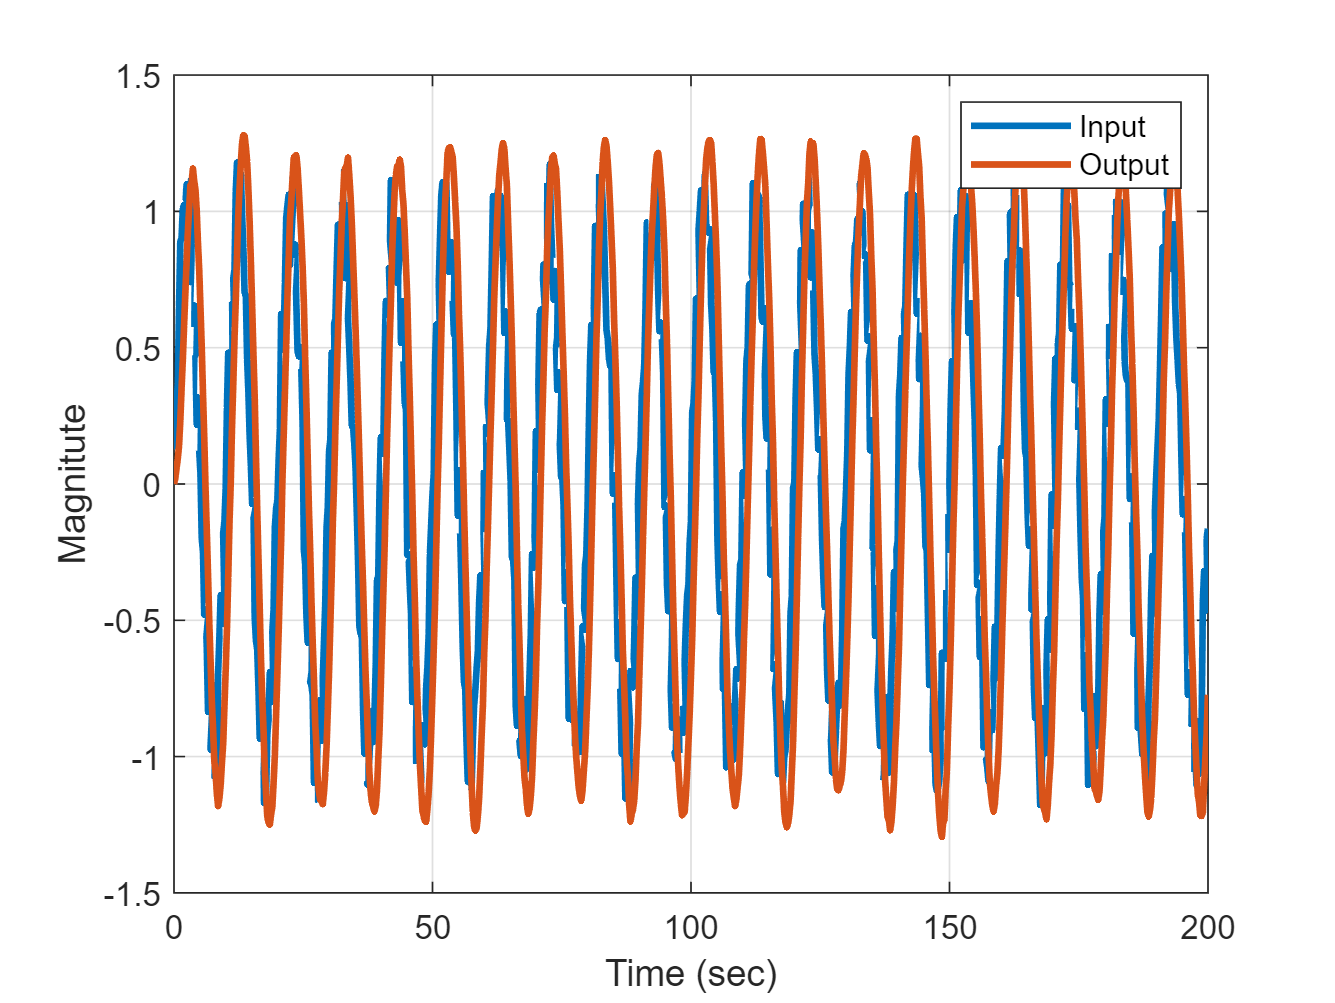

tfinal=200;
t = 0:T_s:tfinal;
u = gensig('sine' , tfinal/20 , tfinal ,T_s);
Noise=(-0.2+(0.2+0.2)*rand(numel(t),1));
u=u+Noise;
y = lsim(sys_dis_open,u ,t);
plot(t,u ,t , y ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Magnitute') ;
grid on
legend('Input','Output') ;

N = numel(y) ;
Parameters_in_den=3

Parameters_in_den = 3

Parameters_in_num=3

Parameters_in_num = 3

Nv=Parameters_in_num+Parameters_in_den;
theta(:,1:Nv) = zeros(Nv , Nv) ;
P = 1e12*eye(Nv) ;
phi=[];
for i = (max(Parameters_in_num,Parameters_in_den)+1):N
    phi(:,i) = [[y(i-1:-1:i-Parameters_in_den)]' , [u(i-1:-1:i-Parameters_in_num)]']';
    K = P*phi(:,i)*(1+phi(:,i)'*P*phi(:,i))^(-1) ;
    P = (eye(Nv) - K*phi(:,i)')*P ;
    theta(:,i) = theta(:,i-1) + K*(y(i) - phi(:,i)'*theta(:,i-1)); 
end

Bode

ident_dis = tf(theta((Parameters_in_num+1):end,end)' ,[1 -theta(1:Parameters_in_num ,end)'], T_s)

ident_dis =
 
   0.1604 z^2 - 0.1958 z + 0.07861
  ----------------------------------
  z^3 - 1.937 z^2 + 1.122 z - 0.1421
 
Sample time: 0.24388 seconds
Discrete-time transfer function.



ident_analog = d2c(ident_dis)

ident_analog =
 
      s^2 + 3 s + 7
  ---------------------
  s^3 + 8 s^2 + 7 s + 7
 
Continuous-time transfer function.



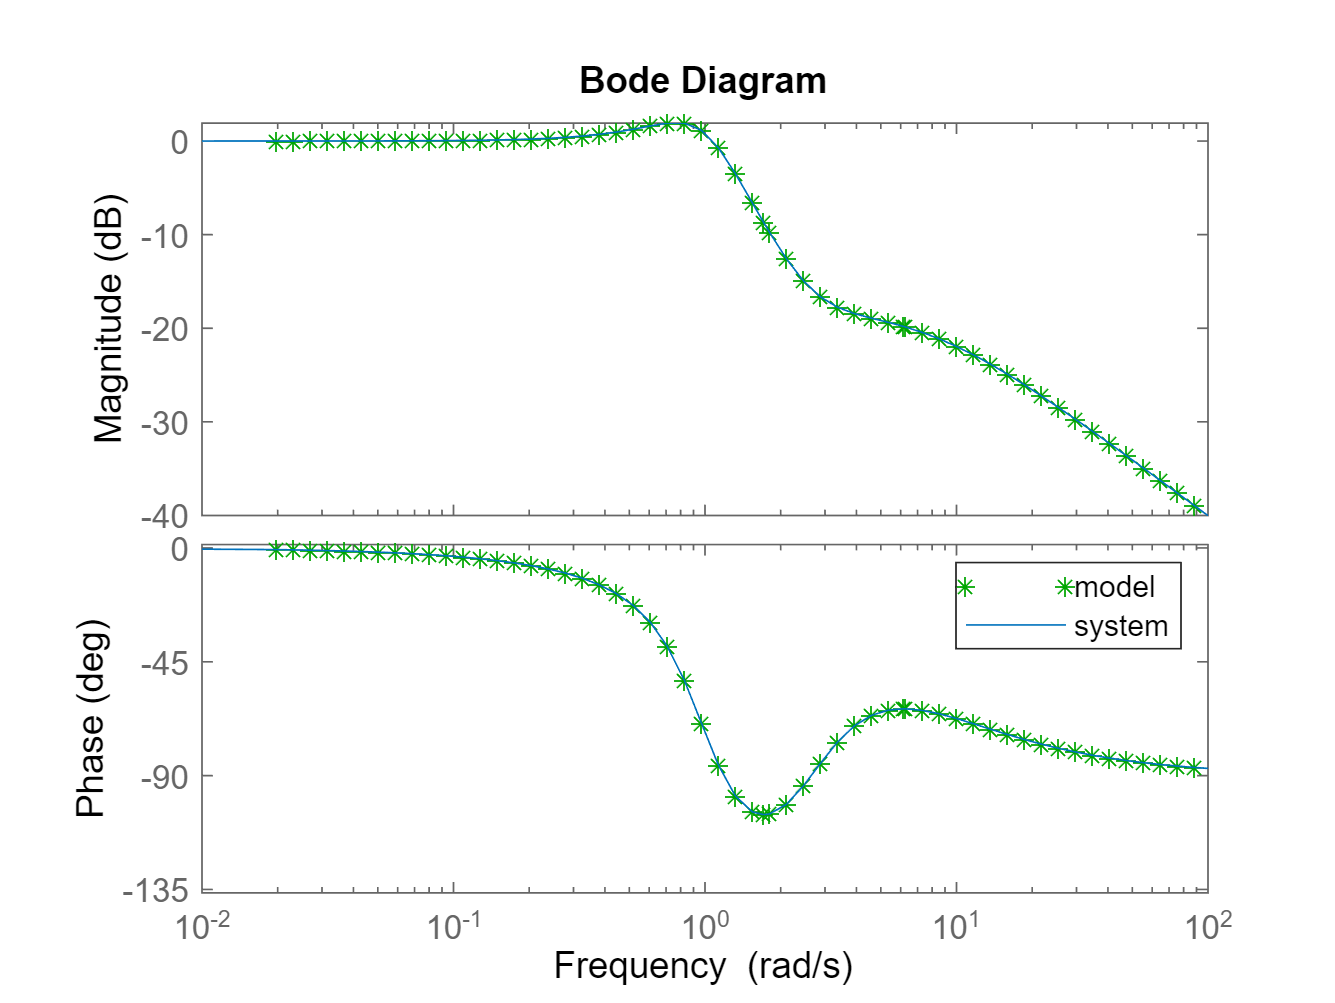

bode(ident_analog ,'g*',sys_cont_open)
legend('model ','system')

RLS Convergence

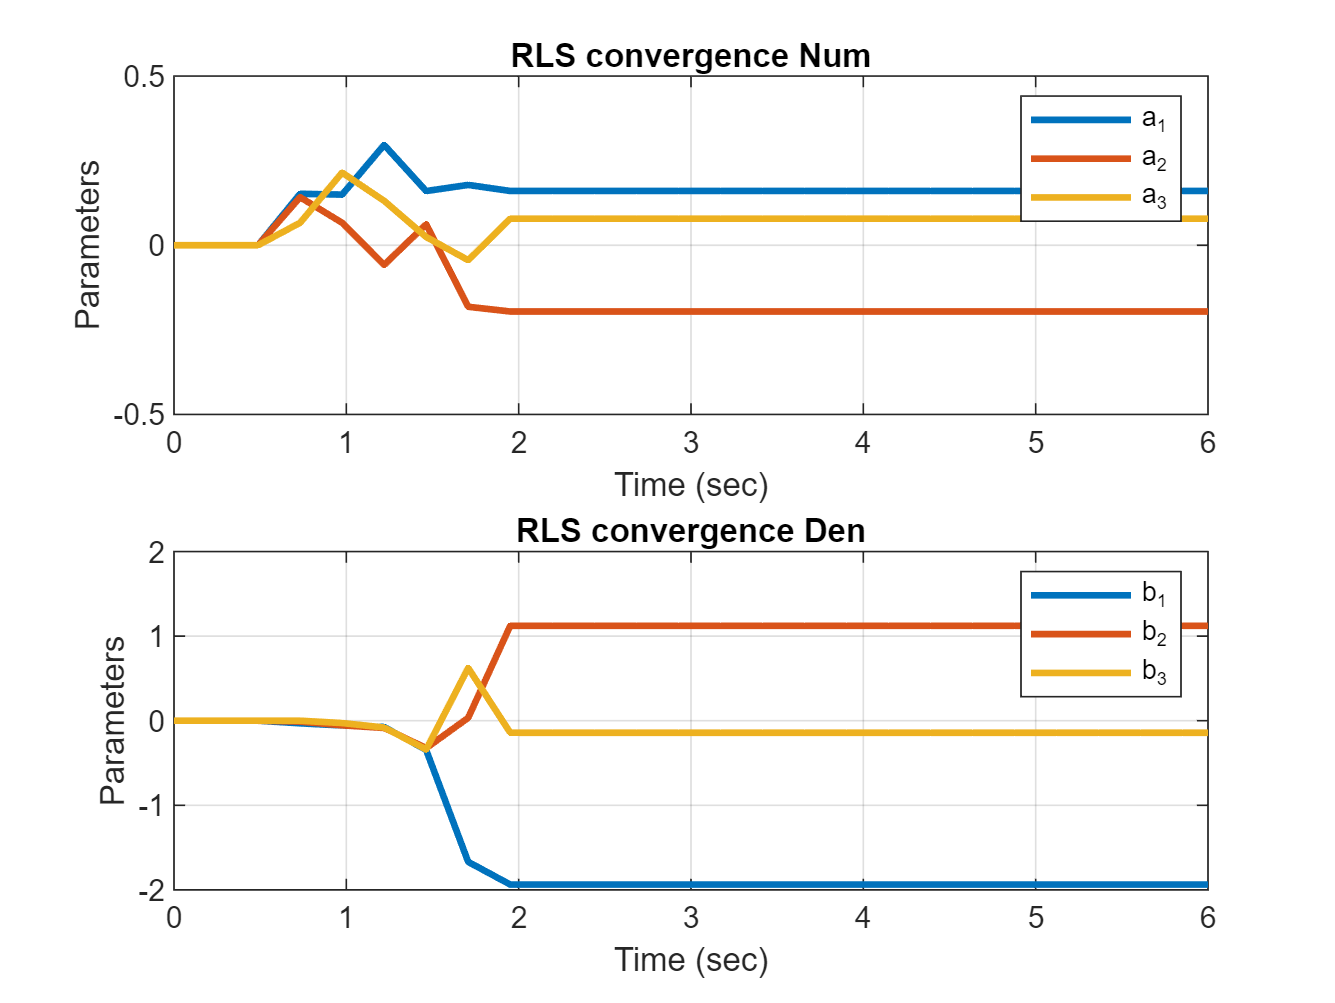

subplot(2,1,1)
plot(t , theta((Parameters_in_num+1):end,:) , 'LineWidth' , 2) ;
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('RLS convergence Num') ;
grid on
legend('a_1','a_2','a_3')
xlim([0 6])
ylim([-0.5 0.5])
%--------------------------------------------------------------
subplot(2,1,2)
plot(t , -theta(1:Parameters_in_num ,:) , 'LineWidth' , 2) ;
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('RLS convergence Den') ;
grid on
legend('b_1','b_2','b_3')
xlim([0 6])
ylim([-2 2])

toc

Elapsed time is 8.618398 seconds.
